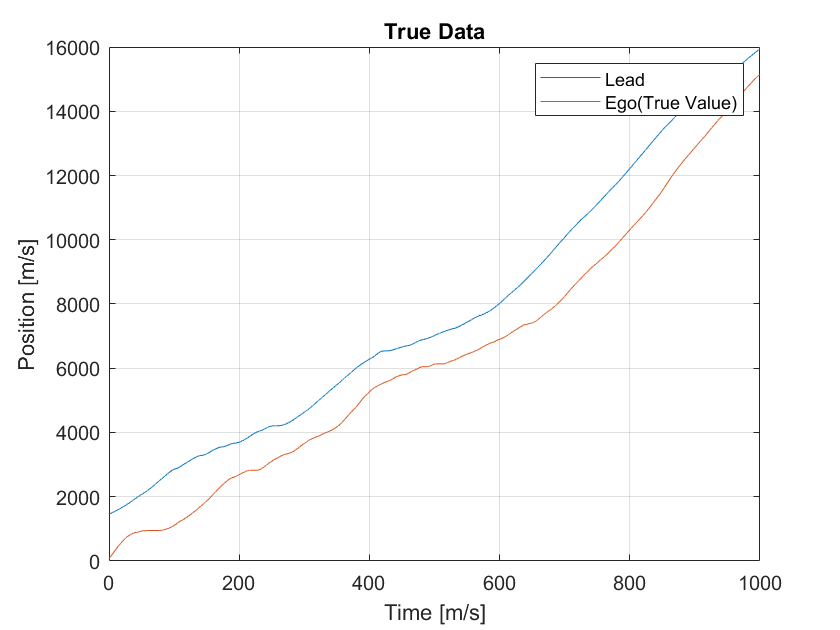


% Written by Anand Singh

clear; close all;

% Dataset contains time, position and speed of two vehicles.
load('Dataset1_vehicle1_vehicle3.mat');

tsft = 1.5;
dsft = 10;
w = dsft/tsft;
m = 80;

xLead = s{2};
tLead = t{2};
xFollow = s{1};
tFollow = t{1};
vLead = v{2};
vFollow = v{1};

tstart = 0;
tdelta = 0.1;
tend = 1000;
tspan = tstart:tdelta:tend;


% Interpolating everything to our own timespan
xLead = interp1(tLead,xLead,tspan);
xFollow = interp1(tFollow,xFollow,tspan);
vLead = interp1(tLead,vLead,tspan);
vFollow = interp1(tFollow,vFollow,tspan);

% Plotting true Trajectory
figure(1); hold on ; box on; grid on;
plot(tspan,xLead) %plotting true of Leading Vehicle
plot(tspan,xFollow) %plotting true of Following vehicle
title("True Data");
ylabel("Position [m/s]");
xlabel("Time [m/s]");
legend("Lead","Ego(True Value)");

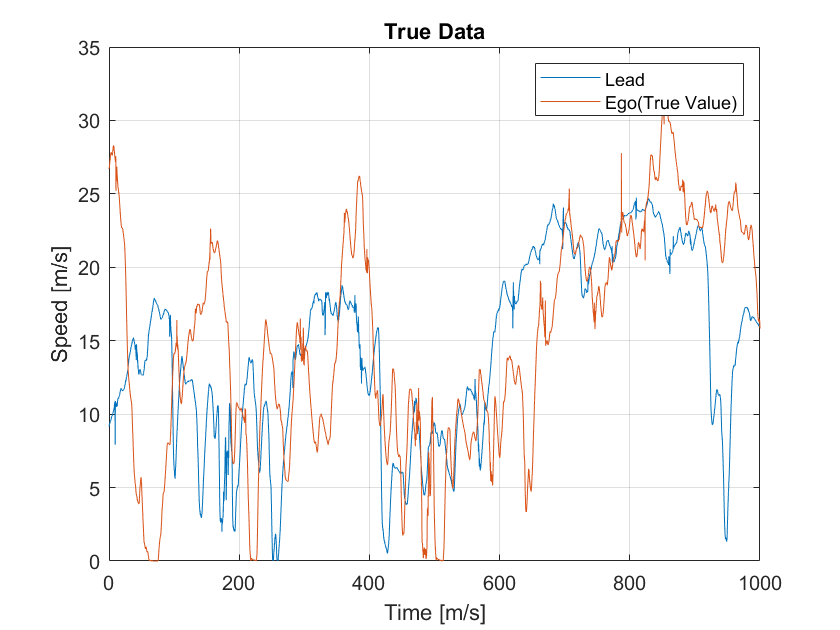


% Plotting true speeds
figure(2); hold on ; box on; grid on;
plot(tspan,vLead) %plotting true of Leading Vehicle
plot(tspan,vFollow) %plotting true of Following vehicle
title("True Data");
ylabel("Speed [m/s]");
xlabel("Time [m/s]");
legend("Lead","Ego(True Value)");

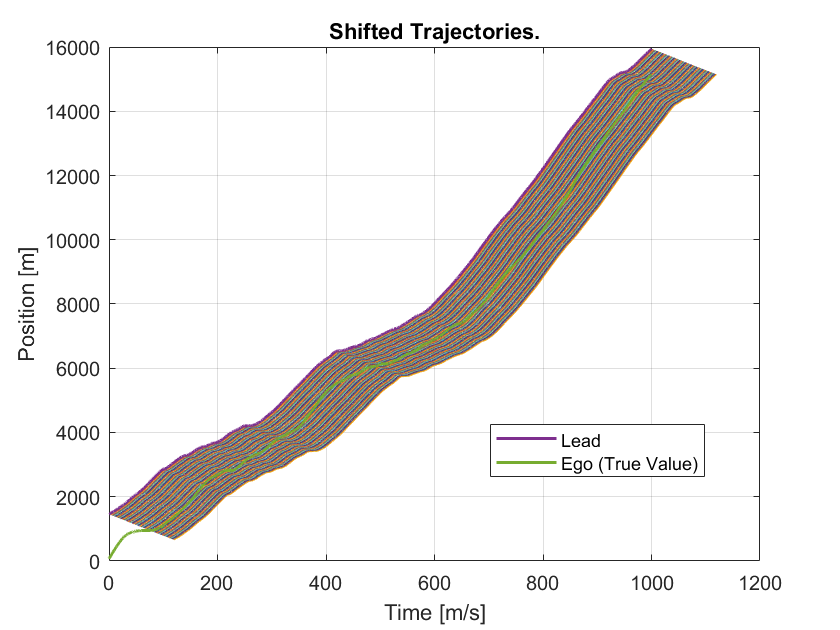


% Calcualting shifted trajectories and values beyond tend.
xLead = [xLead zeros(1,m*tsft/tdelta)];
xFollow = [xFollow zeros(1,m*tsft/tdelta)];
vLead = [vLead zeros(1,m*tsft/tdelta)];
tspan = tstart:tdelta:tend+m*tsft;
xEgo_pred = zeros(m,length(tspan));
for n = 1:m
    xEgo_pred(n,:) = interp1(tspan,xLead,tspan-n*tsft) - n*dsft;    
end
xLead(xLead<=0) = nan;
xFollow(xFollow<=0) = nan;
xEgo_pred(xEgo_pred<=0) = nan;


% Plotting shifted trajectories and values beyond tend.
figure(3);hold on ; box on; grid on;
ylabel("Position [m]");
xlabel("Time [m/s]");
plot(tspan,xEgo_pred); %plotting predicted Following vehicle
p1 = plot(tspan,xLead,"Linewidth",1.5); %plotting true of Leading Vehicle
p2 = plot(tspan,xFollow,"Linewidth",1.5);
title("Shifted Trajectories.");
legend( [p1,p2],{'Lead','Ego (True Value)'},"Location","best")

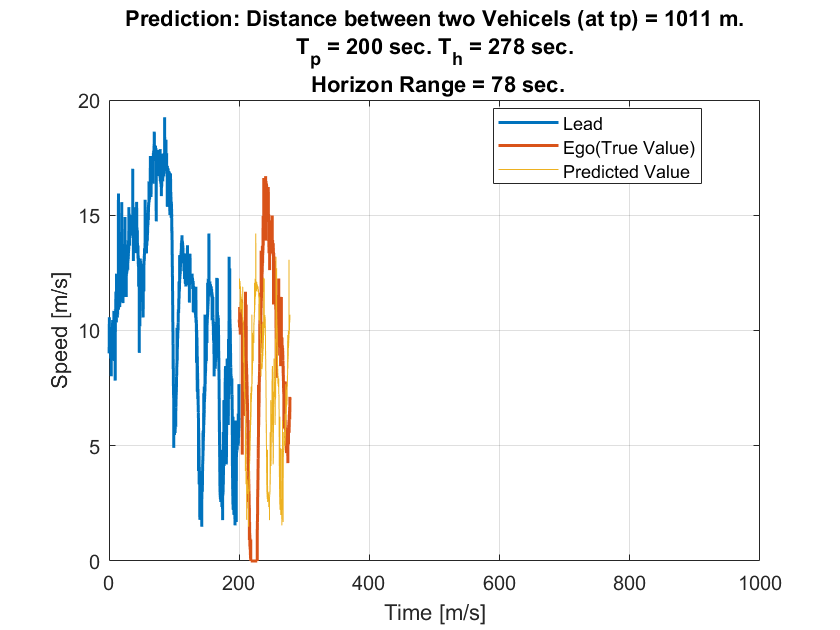



% Choosing the right value from the shifted curves
tp = 200;     %% EDIT
pos_start = find(tspan==tp);
distance = (xLead(pos_start)-xFollow(pos_start));
th = round(tp + distance/(vLead(pos_start)+w),0);
pos_end = find(tspan==th);
horizon = th - tp;


% Plotting trajectory prediction.
figure(4);hold on; box on; grid on;
min = distance;
for n  = 1:m
    if abs(xEgo_pred(n,pos_start)-xFollow(pos_start)) < min
        min = abs(xEgo_pred(n,pos_start)-xFollow(pos_start));
        i = n;
    end     
end  
plot(tspan(1:pos_start),xLead(1:pos_start),"Linewidth",1.5); %plotting true of Leading Vehicle
plot(tspan(pos_start:pos_end),xFollow(pos_start:pos_end),"Linewidth",1.5);
plot(tspan(pos_start:pos_end),xEgo_pred(i,pos_start:pos_end))  % prediction  
xlim([0 1000]);
legend("Lead","Ego(True Value)","Predicted Value","Location","best");
ylabel("Position [m]");
xlabel("Time [m/s]");
title({"Prediction: Distance between two Vehicels (at tp) = "+round(distance,0)+" m.",...
      "T_p = "+tp+" sec. T_h = "+th+" sec.",...
      " Horizon Range = "+horizon+" sec."});

  
% Plotting speed prediction just by differentiating trajectory prediction.
figure(5);hold on; box on; grid on;  
vLead_new = diff(xLead(1:pos_start))./diff(tspan(1:pos_start));
vFollow_new = diff(xFollow(pos_start:pos_end))./diff(tspan(pos_start:pos_end));
vEgo_pred_new = diff(xEgo_pred(i,pos_start:pos_end))./diff(tspan(pos_start:pos_end));
plot(tspan(2:pos_start),vLead_new,"Linewidth",1.5); %plotting true of Leading Vehicle
plot(tspan(pos_start+1:pos_end),vFollow_new,"Linewidth",1.5);
plot(tspan(pos_start+1:pos_end),vEgo_pred_new)  % prediction  
xlim([0 1000]);
legend("Lead","Ego(True Value)","Predicted Value","Location","best");
ylabel("Speed [m/s]");
xlabel("Time [m/s]");
title({"Prediction: Distance between two Vehicels (at tp) = "+round(distance,0)+" m.",...
      "T_p = "+tp+" sec. T_h = "+th+" sec.",...
      " Horizon Range = "+horizon+" sec."});

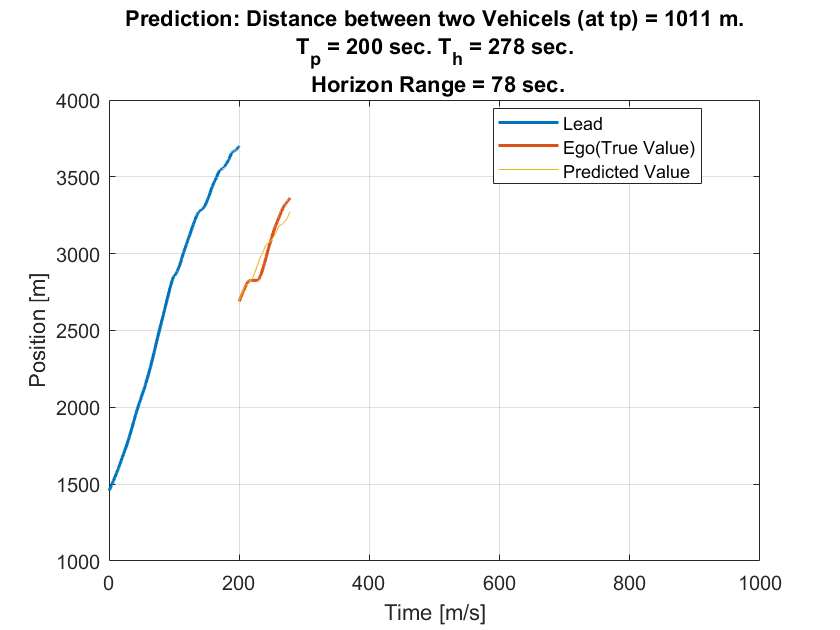

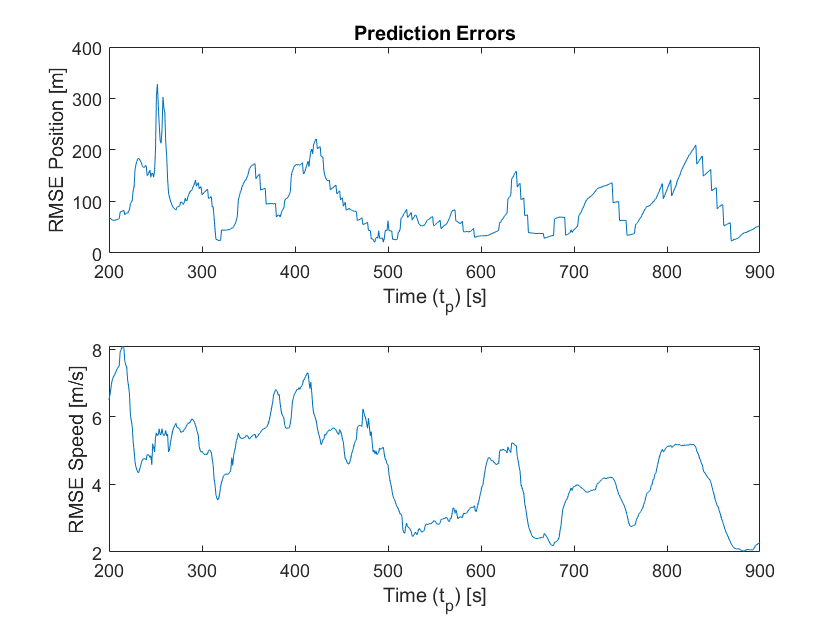



% Error Function
Two_vehicle_prediction_error(xLead,xFollow,vLead,tspan,xEgo_pred,w,m);